# Universidade Federal de Campina Grande

# Programa de Pós-Graduação em Engenharia Elétrica

# Estimação e Identificação de Sistemas - 21.2

## Professores: Antonio Marcus Nogueira Lima, Dr.

##                        **Saulo** Oliveira **Dornellas** Luiz, Dr.

## Aluno: Arthur Dimitri Brito Oliveira

## Relatório de Atividade 6

## Introdução

O objetivo deste relatório é discutir métodos que buscam determinar as funções de transferência diretamente, sem selecionar um conjunto de modelos possíveis. Estes métodos serão apresentados a seguir e baseiam-se na hipótese que é possível injetar um impulso, ou degrau, na entrada do sistema e registrar o sinal de saída por meio de um osciloscópio. A partir da forma de onda obtida, será possível obter diretamente a função de transferência da planta. 

## Análise da resposta transiente e análise da correlação

### Análise da resposta ao impulso

Sendo um sistema descrito por: 


$$y(t) = G_0(t)u(t) + v(t)$$


O sinal de teste pode ser descrito como um impulso:


$$u(t) = \begin{cases}
    \alpha, \:\:t=0 \\
     0, \:\:t \neq 0
\end{cases}$$


A saída é expressa por:


$$y(t) = \alpha g_0(t) + v(t)$$


Caso o ruído seja insignificante, é possível determinar os coeficientes da resposta ao impulso no tempo por meio de uma estimativa:


$$\hat g(t) = \frac{y(t)}{\alpha}$$


A principal desvantagem desse método é que a maior parte dos processos físicos não permite a aplicação de impulsos com amplitude tal que o erro $v(t)/\alpha$ torna-se insignificante comparado aos coeficientes de $\hat g(t)$. Esse tipo de entrada pode causar efeitos não-lineares que perturbariam o comportamento linear do modelo. 

### Análise da resposta ao degrau

De forma análoga, ao aplicar um sinal de entrada na forma:


$$u(t) = \begin{cases}
    \alpha, \:\:t \geq 0 \\
     0, \:\:t <0
\end{cases}$$


Obtem-se:


$$y(t) = \alpha\sum_{k=1}^{t}g_0(k)+v(t)$$


De modo que as estimativas de $g_0(k)$ podem ser obtidas por:


$$\hat g(t) = \frac{y(t)-y(t-1)}{\alpha}$$


Baseado nos gráficos obtidos por meio da resposta ao degrau, é possível obter algumas informações básicas de controle do sistema, como atraso, ganho estático, etc. 

### Análise de correlação

Dada a descrição do modelo dada por:


$$y(t) = \sum_{k=1}^{\infty}g_0(k)u(t-k)+v(t)$$


Sendo a entrada um sinal quasi-estacionário com:


$$\bar E u(t)u(t-\tau)=R_u(\tau)$$


De modo a descorrelacionar a entrada com o ruído na operação em malha aberta:


$$\bar E u(t)v(t-\tau)=0$$


A correlação cruzada entre o sinal de entrada e o sinal de saída pode ser expressa por:


$$\bar E y(t)u(t-\tau) = R_ {yu}(\tau)=\sum_{k=1}^{\infty}g_0(k)R_u(k-\tau)$$


Caso a entrada escolhida seja um ruído branco, tem-se que:


$$R_u(\tau) = \alpha \delta_{\tau 0}$$


Assim, a resposta ao impulso é:


$$g_0(\tau)=\frac{R_{yu}(\tau)}{\alpha}$$


Desse modo, uma estimativa da resposta ao impulso é obtida ao variar $\tau$, encontrando diversas amostras de $g_0(\tau)$:


$$\hat R_{yu}^N(\tau)=\frac{1}{N}\sum_{t=\tau}^{N}y(t)u(t-\tau)$$


Caso o sinal de entrada não possua correlação impulsiva, não sendo assim um ruído branco, devemos estimar:


$$\hat R_{u}^{N}(\tau) = \frac{1}{N}\sum_{t=\tau}^{N}u(t)u(t-\tau)$$


E resolver a correlação cruzada que também não é mais impulsiva:


$$\hat R_{yu}^{N} (\tau)=\sum_{k=1} ^{M} \hat g(k)\hat R_u^N(k - \tau)$$


### Técnicas de resposta em frequência

#### Teste com sinal senoidal

Tendo uma entrada cossenoidal do tipo:

$u(t) = \alpha \cos(\omega t)$,   $t=0,1,2,...$

A saída será dada por:


$$y(t) = \alpha |G_0(e^{j\omega})|\cos(\omega t + \varphi)+v(t)$$



$$\varphi=\arg G_0(e^{j\omega})$$


Essa propriedade dá algumas pistas para o cálculo de $G_0(e^{j\omega} )$. Sabendo os dados do sinal de entrada, determina-se a amplitude e o deslocamento de fase do sinal cossenoidal de saída. Calcule uma estimativa $\hat G_N(e^{j\omega})$ com essas informações. Isso deve ser rpetido para uma gama de frequências dentro da banda de interesse. 

#### Análise de frequência pelo método de correlação

Agora utiliza-se uma modulação da seguinte forma:


$$I_C(N) = \frac{1}{N}\sum_{t=1}^{N}y(t)\cos \omega t$$



$$I_S(N)=\frac{1}{N} \sum_{t=1}^{N} y(t)\sin \omega t$$


Substituindo a equação do sinal de saída nas expressões anteriores:


$$I_C(N)=\frac{1}{N}\sum_{t=1}^{N}\alpha|G_0(e^{j\omega})|\cos(\omega t+\varphi)\cos(\omega t)+\frac{1}{N}\sum_{t=1}^{N}v(t)\cos(\omega t)$$



$$I_C(N)=\frac{\alpha}{2}|G_0(e^{j\omega})|\cos \varphi + \alpha|G_0(e^{j\omega})|\frac{1}{2}\frac{1}{N}\sum_{t=1}^{N} \cos(2\omega t+\varphi)+\frac{1}{N}\sum_{t=1}^{N} v(t)\cos(\omega t)$$



$$I_S(N)=-\frac{\alpha}{2}|G_0(e^{j\omega})|\sin\varphi + \alpha|G_0(e^{j\omega})|\frac{1}{2}\frac{1}{N}\sum_{t=1}^{N} \sin(2\omega t+\varphi)+\frac{1}{N}\sum_{t=1}^{N} v(t)\sin(\omega t)$$


O segundo termo de ambas as equações tende a zero à medida em que $N$tende ao infinito, bem como o terceiro termo, que tem um decaímento na sua variância se $\sum_{0}^{\infty}\tau|R_v(\tau)|<\infty$. Então, a partir de $I_C(N)$ e $I_S(N)$, tem-se as amplitudes e fases da resposta em frequência:


$$|\hat G_N(e^{j\omega})| = \frac{\sqrt{I_c^2(N)+I_s^2(N)}}{\alpha^2/2}$$



$$\hat \varphi_N = \arg \hat G_N(e^{j\omega})=-\arctan\frac{I_s(N)}{I_c(N)}$$


Este teste provê o valor na frequência $\omega$ do sinal de excitação. 

#### A relação com a análise de Fourier

A partir da representação do sinal de saída por meio da DFT:


$$Y_N(\omega)=\frac{1}{\sqrt N}\sum_{t=1}^{N}y(t)e^{-j\omega t}$$


Por meio da relação de Euler $e^{-j\omega} = \cos(\omega)-j\sin (\omega)$, tem-se que os sinais $I_c(N) $ e $I_s(N)$ podem ser escritos como:


$$I_c(N)-jI_s(N)=\frac{1}{\sqrt N}Y_N(\omega)$$



$$U_N(\omega) = \frac{\sqrt N \alpha}{2}$$


Reescrevendo a equação do módulo da função de transferência, tem-se:

        $\hat G_N(e^{i\omega})=\frac{\sqrt N Y_N(\omega)}{N\alpha/2} = \frac{Y_N(\omega)}{U_N(\omega)}$        (1)

### Análise de Fourier

#### Estimaçao empírica da função de transferência

A expressão anterior corresponde à análise de frequência com uma única senoide de frequência $\omega$ injetada como entrada. Esse tipo de aproximação é errático quando houver termos de ruído, o que implica em DFTs ruídosas. Diante diso, define-se $\hat \hat G_N(e^{j\omega} )$ como uma estimativa grosseira da função de transferência. Apesar da facilidade do cálculo da expressão associada, a interpretação da curva pode ser problemática devido ao ruído. 

#### Propriedades da EEFT

Assumindo que o sistema tem forma $y(t) = G_0(q)u(t) + v(t)$, introduz-se:


$$V_N(\omega) = \frac{1}{\sqrt N} \sum_{t=1}^{N}v(t)e^{-j\omega t}$$


A expressão a seguir revela o $G_0$ que deseja-se encontrar, mas existem o resíduo pelo truncamento $R_N$ e termo de ruído $V_N$:


$$\hat \hat G_N(e^{j\omega} ) = G_0(e^{j\omega}) + \frac{R_N(\omega)}{U_N(\omega)} + \frac{V_N(\omega)}{U_N(\omega)}$$


Assumindo que $v(t)$tem média nula, $E(V_N(\omega)) = 0,$ ao tomar a esperança da expressão anterior, tem-se:


$$E \hat \hat G_N(e^{j\omega} ) = G_0(e^{j\omega})+\frac{R_N(\omega)}{U_N(\omega)}$$


O valor médio será função da excitação imposta ao sistema. A princípio, seria possível manipular o sinal de entrada de modo a zerar a parcela $\frac{R_N(\omega)}{U_N(\omega)}$. 

Analisando como a variância do ruído afeta a estimativa, tem-se que:


$$EV_N(\omega)V_N(-\xi) = \begin{cases}
\Phi_v(\omega)+\rho_2(N), \:\:\: se \:\: \xi=\omega \\
\rho_2(N), \:\: se \:\: |\xi - \omega| = \frac{k2\pi}{N}
\end{cases}$$


Com $|\rho_2(N)| \leq 2C/N$. Assim, o modelo a ser estimado tem um $G_0(q)$, e deseja-se analisar as propriedades da estimativa utilizando a EEFT. Quanto à média e à variância, pode-se controlar as polarizações $|\rho_1(N)|\leq\frac{C_1}{\sqrt N}$  e $| \rho_2(N)| \leq \frac{C_2}{N}$. O erro em torno da função de transferência $G_0$ pode ser manipulado, mediante o projeto de sinais específicos, de modo que os erros da média e da variância sejam mínimos. As constantes podem ser calculadas por:


$$C_1 = \left (2 \sum_{k=1}^{\infty}|kg_0(k)|\right).\max|u(t)|$$



$$C_2 = C^2_1 + \sum_{k=-\infty}^{\infty}|\tau R_v(\tau)|$$


Antecipando as conclusões a partir das demonstrações, ao utilizar a DFT para EEFT, no caso de sinais de entrada periódicos, a estimativa tende a melhoras nas frequências que estão presentes na entrada. No entanto, quando o sinal não é periódico, a variância não decai com N, mas mantém-se igual à relação sinal-ruído nas frequências correspondentes. Em qualquer um dos casos, se houver a contaminação com ruído dos sinais, as estimativas tendem a ser grosseiras para a maioria dos casos. 

### Análise Espectral

#### Suavizando a EEFT

Suponha que existe uma função suave $G_0(e^{j\omega})$, e que a distância $\frac{2\pi}{N}$ é pequena quando comparada à mudança de $G_0(e^{j\omega})$, ou seja, há muitas raias espectrais. O valor ao redor dele pode ser considerado constante $2\pi k /N \approx\omega$. Assim os valores de $\hat \hat G_N(e^{2\pi i k/N})$ são estimativas descorrelacionados da mesma frequência $G_0$. Considera-se então que, em torno da frequência $\omega$, existem dois indicadores $k_1$ e $k_2$ que cercam a frequência central $\omega$. O objetivo é correlacionar as estimativas para melhorar a estimativa de $\omega$. A estimativa normalizada é ponderada em termos da estimativa grosseira. Há maior peso atribuído, na ponderação, às frequências que têm melhor relação sinal-ruído. $\hat G_N$. Portanto, explora-se a correlação que melhora a estimativa inicial para a frequência central:


$$\alpha_k = \frac{|U_N(2\pi k/N)|^2}{\Phi_v(2\pi k/N) }$$


        $\hat G_N(e^{j\omega} ) = \frac{\sum_{k=k_1}^{k_2}\alpha_k \hat \hat G_N(e^{2\pi i k/N})}{\sum_{k=k_1}^{k_2}\alpha_k}$        (2)

A ideia agora é tornar o N grande de tal forma que essa ponderação se torna refinada com passo infinitesimal. Assim, $k_1$ e $k_2$ tornam-se $\omega_0 - \Delta_\omega$ e $\omega_0 + \Delta_\omega$ e tem-se a aproximação de $\hat G_N$ como sendo:


$$\hat G_N(e^{j\omega}) = \frac{ \int_{\omega_0-\Delta_\omega}^{\omega_0+\Delta_\omega}\alpha(\xi)\hat \hat G_N(e^{i\xi})d\xi}{\int_{\omega_0-\Delta_\omega}^{\omega_0+\Delta_\omega}\alpha(\xi)d\xi}$$



$$\alpha(\xi) = \frac{|U_N(\xi)|}{\Phi_v(\xi)}$$


Para mitigar os efeitos de borda ao trabalhar com uma quantidade finita de dados, utiliza-se uma janela de ponderação para melhorar a estimativa, utiliza-se a função (janela) de ponderação $W_\gamma$ como sendo um degrau:   


$$\hat G_N(e^{j\omega}) = \frac{\int_{-\pi}^{\pi}W_\gamma(\xi - \omega_0)\alpha(\xi)\hat \hat G_N(e^{j\xi})d\xi}{\int_{-\pi}^{\pi}W_\gamma(\xi - \omega_0)\alpha(\xi)d\xi}$$


No caso, pode-se utilizar funções de ponderação mais complexas. Ao fazer aparecer explicitamente o espectro do sinal de entrada, tem-se:

$\hat G_N(e^{j\omega}) = \frac{\int_{-\pi}^{\pi}W_\gamma(\xi - \omega_0)|U_N(\xi)|^2\hat \hat G_N(e^{j\xi})d\xi}{\int_{-\pi}^{\pi}W_\gamma(\xi - \omega_0)|U_N(\xi)|^2d\xi}$        (3)

Então, é possível utilizar diversos tipos de janelas de ponderação de modo que a função de transferência seja suavizada, e este é o mesmo princípio utilizado no capítulo 2 ao suavizar o periodograma utilizando $\psi(\omega)$ e o converge para o espectro.

### Desenvolvimento

Dado um sistema da forma:


$$y(t) - 1.5y(t-1) + 0.7y(t-2) = u(t-1)+0.5u(t-2)+e(t)$$


Onde $e(t)$ é um ruído branco de variância unitária e $u(t)$ é um sinal PRBS.  Utilizando o operador de deslocamento no tempo, a função de transferência real do sistema pode ser escrita conforme a Eq. 4


$$y(k) -1.5y(k)q +0.7y(k)q^2 =u(k)q + 0.5u(k)q^2$$


            $H(z) = \frac{z + 0.5z}{0.7z^2 - 1.5z + 1}$        (4)

Os sinais $y(t)$e $u(t)$podem ser visualizados na Fig.1.

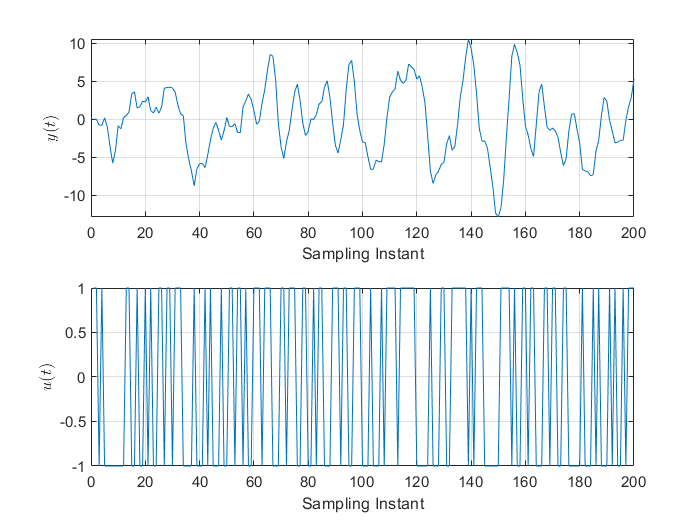

[y,u] = simulateSystem(1000);
figure()
subplot(2,1,1)
plot(y(1:200))
ylabel('$y(t)$', "Interpreter","latex")
xlabel('Sampling Instant')
grid()
subplot(2,1,2)
plot(u(1:200))
ylabel('$u(t)$', "Interpreter","latex")
xlabel('Sampling Instant')
grid()

**Fig.1: **Sinal de saída $y(t)$ e sinal de entrada $u(t)$.

Conforme a Eq.1, a funçao de transferência empírica pode ser obtida. O resultado é uma estimativa grosseira da função de transferência do sistema:

    $\hat \hat G_N(e^{j\omega})=\frac{Y_N(\omega)}{U_N(\omega)}$        (5)

    
$$Y_N(\omega)=\frac{1}{\sqrt N}\sum_{t=1}^{N}y(t)e^{-j\omega t}$$


    
$$U_N(\omega)=\frac{1}{\sqrt N}\sum_{t=1}^{N}u(t)e^{-j\omega t}$$


De modo a suavizar a estimativa, algumas janelas podem ser utilizadas:

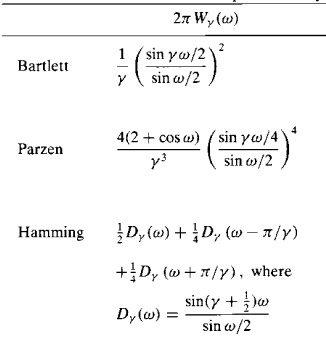

**Figura 2: **Janelas utilizadas para análise espectral. 

A função de transferência suavizada é, por sua vez:

        $\hat G_N(e^{j\omega}) = \frac{\int_{-\pi}^{\pi}W_\gamma(\xi - \omega_0)|U_N(\xi)|^2\hat \hat G_N(e^{j\xi})d\xi}{\int_{-\pi}^{\pi}W_\gamma(\xi - \omega_0)|U_N(\xi)|^2d\xi}$        (6)

Também é possível utilizar o espectro do sinal de entrada obtido a partir da correlação do sinal de entrada. À medida que $N \rightarrow \infty$, $|U_N(\xi)|^2 \rightarrow\Phi_u(\xi)$. Dessa forma o numerador e o denominador da Eq. 6 podem ser reescritos como:

            $\hat G_N(e^{j\omega}) = \frac{\int_{-\pi}^{\pi}W_\gamma(\xi - \omega_0)\Phi_u(\xi)\hat \hat G_N(e^{j\xi})d\xi}{\int_{-\pi}^{\pi}W_\gamma(\xi - \omega_0)\Phi_u(\xi)d\xi} = \frac{\hat \Phi_{yu}^N(\omega_0)}{\hat \Phi_u^N(\omega_0}$     (7)

As Figuras 2, 3 e 4 ilustram um comparativo entre a função de transferência real do sistema e as suas aproximações. Utilizou-se o procedimento direto obtido pela divisão entre as DFTs do sinal de entrada e o sinal de saída, bem como as suavizações utilizando janelas via DFT do sinal de entrada ou da correlação do sinal de entrada.

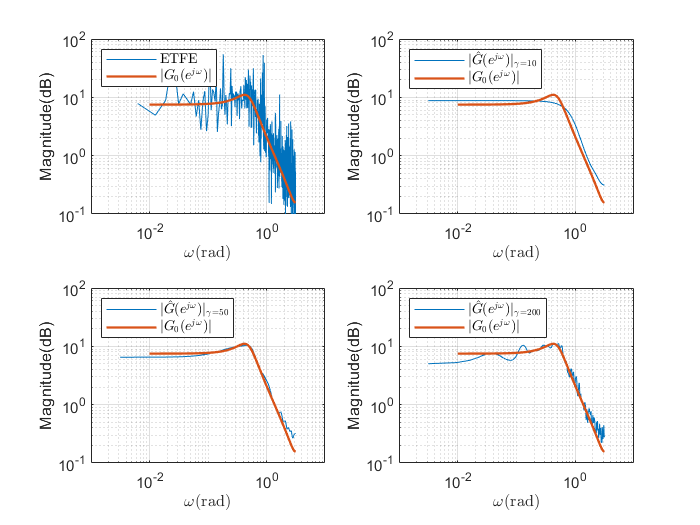

empirical_TF_and_smooth_by_parzen

**Fig. 2: **Comparativos entre a função de transferência ideal e suas aproximações via ETFE e janelamento de Parzen. 

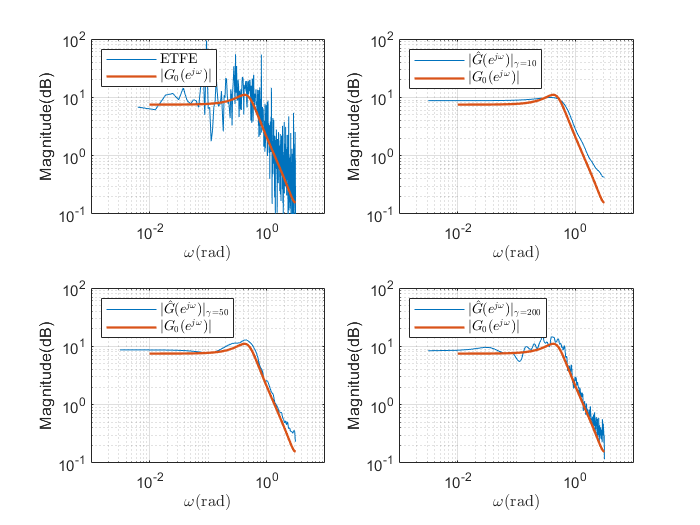

empirical_TF_and_smooth_by_bartlett

**Fig. 3: **Comparativos entre a função de transferência ideal e suas aproximações via ETFE e janelamento de Bartlett. 

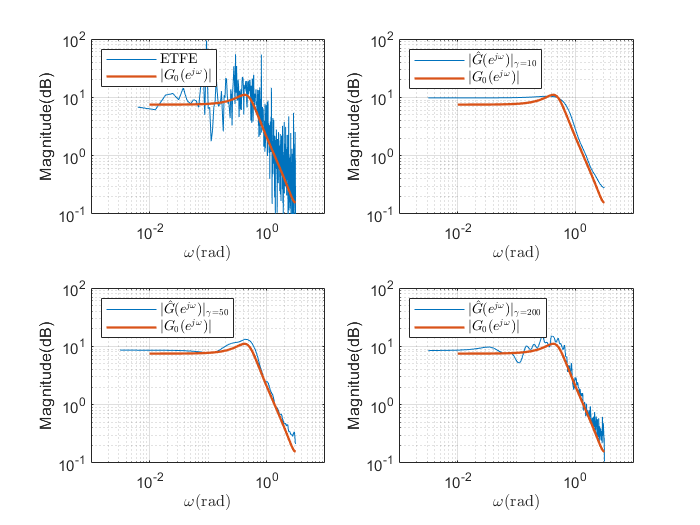

empirical_TF_and_smooth_by_hamming

**Fig. 4: **Comparativos entre a função de transferência ideal e suas aproximações via ETFE e janelamento de Hamming. 

Como esperado, a razão entre as DFTs da entrada e da saída resulta em uma aproximação grosseira. Mediante a utilização da Eq.6, é possível suavizar a curva obtida a partir da ETFE utilizando as janelas de Parzen, Bartlett e Hamming. Para todas estas, nota-se que à medida em que incrementa-se o valor de $\gamma$, há oscilações na magnitude da função de transferência suavizada. Isso é esperado, já que, na ponderação da estimativa grosseira, explora-se frequências com melhor relação sinal ruído. Quando a janela torna-se mais larga, pondera-se frequências que estão cada vez mais distantes da frequência central $\omega$, contribuindo para um viés elevado e oscilações mais severas na suavização de $\hat \hat G(e^{j\omega})$. No caso do sistema em questão, a janela ótima em termos de viés e variância é $\gamma=50$.

Outra abordagem possível é utilizar o espectro do sinal de entrada obtido a partir da correlação do sinal de entrada, valendo-se da relação$N \rightarrow \infty$, $|U_N(\xi)|^2 \rightarrow\Phi_u(\xi)$, conforme a Eq. 7. Os comparativos ilustrados nas Figuras 5, 6 e 7 para cada uma das janelas, variando $\gamma = [10, \:\:50, \:\:200]$, evidenciam que a aproximação previamente mencionada, onde o módulo da DFT do sinal $u(t)$converge para o espectro $\Phi_u$ à medida em que o número de amostras tende a infinito, não foi constatada. Tais aproximações podem ser melhoradas ao incrementar-se o número de amostras $N$utilizadas para geração do sinais $y(t)$e $u(t)$. 

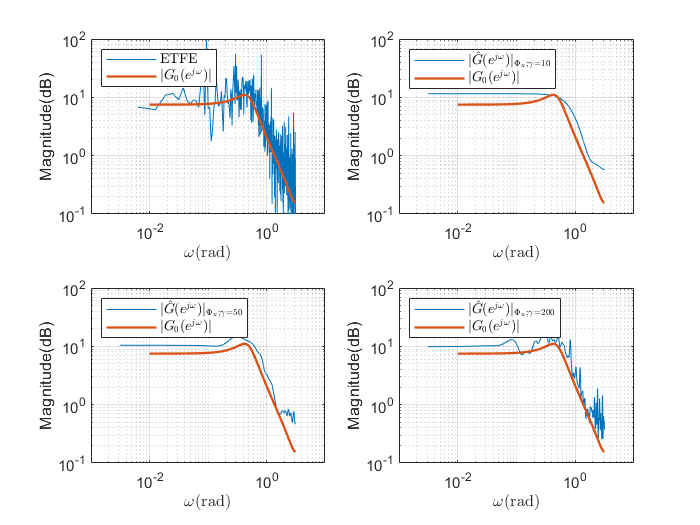

empirical_TF_and_smooth_blackman_turkey_parzen

**Fig. 5: **Comparativos entre a função de transferência ideal e suas aproximações via ETFE e janelamento Parzen via correlação. 

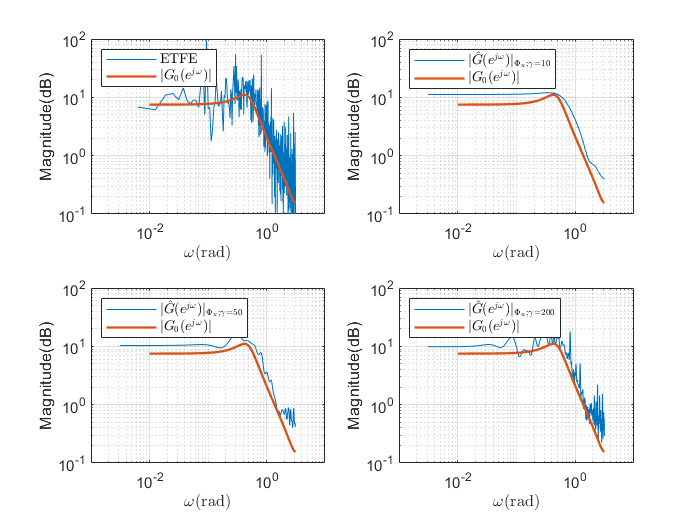

empirical_TF_and_smooth_blackman_turkey_bartlett

**Fig. 6: **Comparativos entre a função de transferência ideal e suas aproximações via ETFE e janelamento Bartlett via correlação. 

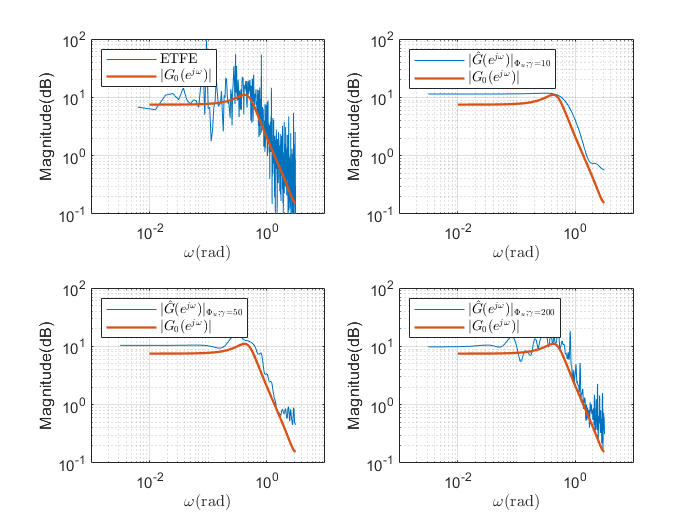

empirical_TF_and_smooth_blackman_turkey_hamming

**Fig. 7: **Comparativos entre a função de transferência ideal e suas aproximações via ETFE e janelamento Hamming via correlação. 

## Referências

[1]   L. LJUNG.** System Identification: Theory for the User **Courier Corporation, 2008. ISBN 0486462781.